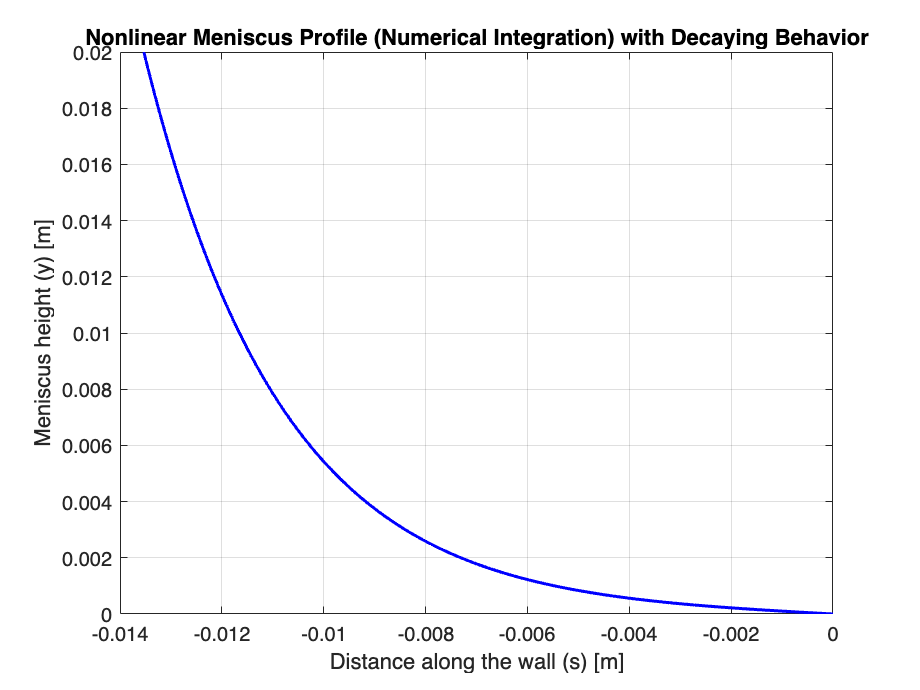

%figure 4
% Parameters
gamma = 72e-3; % Surface tension [N/m]
rho = 1000; % Density of water [kg/m^3]
g = 9.81; % Gravitational acceleration [m/s^2]
Lc = sqrt(gamma / (rho * g)); % Capillary length [m]
H = 0.02; % Maximum meniscus height [m]

% Choose a proper constant C that avoids negative sqrt terms
C = 2 / Lc^2 + 0.01; % Ensure C is slightly larger than 2/Lc^2 to prevent negatives

% Define the integral for numerical solution with reversed limits of integration
f = @(y) 1 ./ sqrt(C - (2 / Lc^2) * cos(y)); % Ensure valid square root

% Restrict y-values to valid domain where argument inside sqrt is non-negative
y_vals = linspace(0, H, 500); % Use values within the expected meniscus height range
s_vals = zeros(size(y_vals)); % Initialize array for s values

% Numerically solve the integral with the reversed limits
for i = 1:length(y_vals)
    % Check for valid argument inside the square root
    if C - (2 / Lc^2) * cos(y_vals(i)) > 0
        s_vals(i) = integral(f, y_vals(i), 0); % Compute integral with reversed limits
    else
        s_vals(i) = NaN; % Assign NaN if the square root argument is negative
    end
end

% Remove invalid points (NaNs) to avoid plotting errors
valid_idx = ~isnan(s_vals);
s_vals = s_vals(valid_idx);
y_vals = y_vals(valid_idx);

% Plot the numerical solution with the correct decaying behavior
figure;
plot(s_vals, y_vals, 'b-', 'LineWidth', 1.5);
xlabel('Distance along the wall (s) [m]');
ylabel('Meniscus height (y) [m]');
title('Nonlinear Meniscus Profile (Numerical Integration) with Decaying Behavior');
grid on;